# 向下重采样测试

clear all
orgInterval=0.01;%原采样间隔
orgFs=1/orgInterval;%原采率
orgCutFre=orgFs/2;%原截止频率=1/2采样率
newInterval=0.02;%新采样间隔
newFs=1/newInterval;%新采样率
noRatio=newInterval/orgInterval;%新采样间隔/原采样间隔
odatLength=4096;%原数据点数
ndatLength=floor(odatLength*orgInterval/newInterval);%新数据长度
zeta=newFs/(2*orgCutFre);%重采样的低通滤波器参数
n=0:odatLength-1;
t=n/orgFs;
xn0=sin(2*pi*1*t)+0.5*sin(2*pi*30*t);   %是否是1和30Hz混合信号
xn1=sin(2*pi*1*newInterval)+0.5*sin(2*pi*30*newInterval);
n1=0:ndatLength-1;
newInterval=n1/newFs;


Nf=100; 
for m=floor(Nf/noRatio)+Nf+1:ndatLength-floor(Nf/noRatio)-1
    x(m)=0;
    for n=floor(m*noRatio)-Nf:1:floor(m*noRatio)+Nf
        x(m)=x(m)+zeta*xn0(n)*sinc(zeta*(m*noRatio-n));
    end
end
xl=length(x);
n1=0:ndatLength-1;
tt1=n1/newFs;
nn1=length(n1);

ntt1=length(tt1);
nx=length(x);
ty=0:0.001:odatLength*orgInterval-Nf/orgFs;
z=sin(2*pi*1*(ty+Nf/orgFs-0.01))+0.5*sin(2*pi*30*(ty+Nf/orgFs-0.01));
n=0:1:(odatLength-1);
f=n*orgFs/odatLength;
xn0fft=abs(fft(xn0,odatLength));


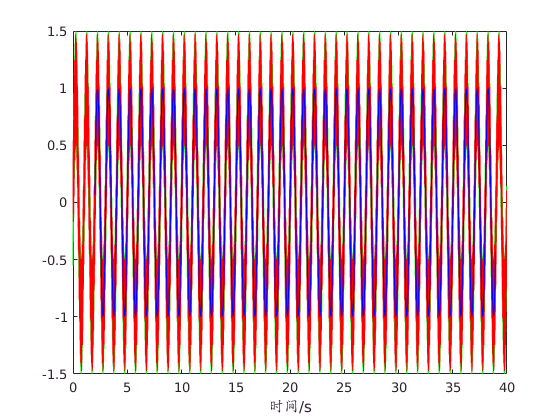

figure(1);
%subplot(2,1,1)
plot(ty,z,'g')
hold on
t100 = t(1+1:odatLength-Nf);
xn0100 = xn0(1+Nf:odatLength-1);
plot(t100,xn0100,'r');
hold on
%蓝线是向下重采样的结果.在重采样的同时已实现了低通滤波
tt150 = tt1(floor(Nf/noRatio)+Nf+1-newFs+1:ndatLength-floor(Nf/noRatio)-1-newFs+1);
x50 = x(floor(Nf/noRatio)+Nf+1:ndatLength-floor(Nf/noRatio)-1);
plot(tt150,x50,'b');

%{
subplot(2,1,2)
shoLength = floor(length(ty)/10);
plot(ty(shoLength*4:shoLength*6),z(shoLength*4:shoLength*6),'g')
hold on  
shoLength = floor(length(t100)/10);
plot(t100(shoLength*4:shoLength*6),xn0100(shoLength*4:shoLength*6),'r');
hold on
shoLength = floor(length(tt150)/10);
plot(tt150(shoLength*4:shoLength*6),x50(shoLength*4:shoLength*6),'b');
hold on
%}
% 重采样+低通滤波
xlabel('时间/s')

figure(2);
subplot(4,1,1);
plot(f,xn0fft*2/odatLength);
title('(a)   100sps采样的频谱')
zfft=abs(fft(z,32768));
n=0:1:(32768-1);
fz=n/(32768*0.001);
subplot(4,1,2);
plot(fz,2*zfft/32768);title('(b)   1000sps采样的频谱');
subplot(4,1,4)
Nx=length(x)

Nx = 1997

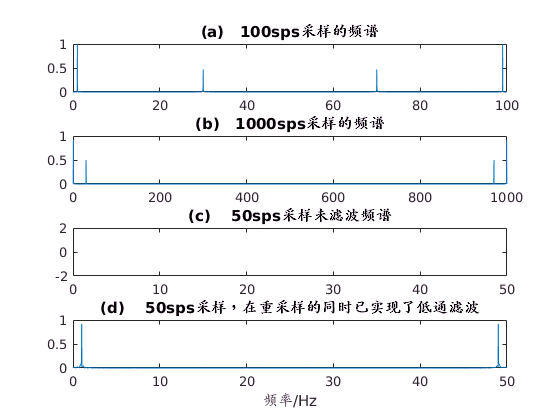

xfft=abs(fft(x));
n=0:1:Nx-1;
fx=n*newFs/Nx;
plot(fx,2*xfft/Nx);
xlabel('频率/Hz');
title('(d)    50sps采样，在重采样的同时已实现了低通滤波');
subplot(4,1,3);
xn1fft=abs(fft(xn1));
fxn1=n1*newFs/ndatLength;
plot(fxn1,xn1fft*2/Nx);
title('(c)    50sps采样未滤波频谱');

figure(3);
%用样条函数（spline)模拟信号恢复
%Dt=0.00005;t=-0.005:Dt:0.005;
subplot(2,1,1)
plot(t(1:100),xn0(1:100));
title('x=sin(2*pi*1*t)+0.5*sin(2*pi*30*t),采样率100sps');
subplot(2,1,2)
ty1=0:0.001:odatLength*orgInterval;
n=0:odatLength-1;
t=n/orgFs;
nty1=length(ty1)

nty1 = 40961

nxn0=length(xn0)

nxn0 = 4096

nnt0=length(n*orgInterval)

nnt0 = 4096

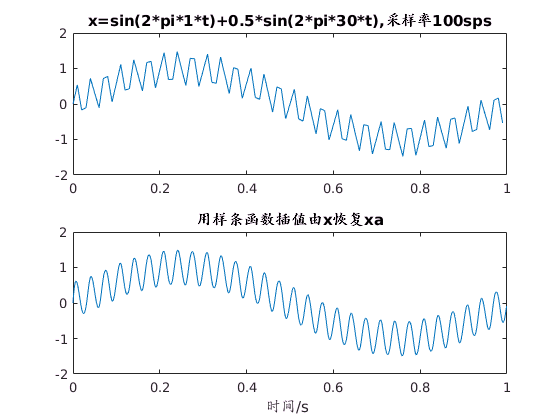

xa=spline(n*orgInterval,xn0,ty1);
plot(ty1(1:1000),xa(1:1000))
title('用样条函数插值由x恢复xa');
xlabel('时间/s ');